**Analysis of Foundation Foods DataBase (USDA)**

Load data and set graphics

% graphics
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% Foundation DB
load('FoundationFoodfromAPI')

Data cleaning

% multiple ids for food name
uniquefoods=unique(EdgeListFoundationFoods.foodname);
multipleids=zeros(length(uniquefoods),1);
keepfirstid=zeros(length(uniquefoods),1);
for ind=1:length(uniquefoods)
    v=unique(EdgeListFoundationFoods.fid(strcmpi(uniquefoods{ind}, EdgeListFoundationFoods.foodname)));
    multipleids(ind)=length(v);
    keepfirstid(ind)=v(1);
end

disp('Number of foods with multiple ids')

Number of foods with multiple ids


disp(sum(multipleids>1))

    47




% Remove all the values different from zero
EdgeListFoundationFoodsNZ=EdgeListFoundationFoods(EdgeListFoundationFoods.valgrams~=0,:);
EdgeListFoundationFoodsNZ.LogValues=log(EdgeListFoundationFoodsNZ.valgrams);
filterid=ismember(EdgeListFoundationFoodsNZ.fid, keepfirstid);
EdgeListFoundationFoodsNZ=EdgeListFoundationFoodsNZ(filterid,:);

%check
uniquefoods=unique(EdgeListFoundationFoodsNZ.foodname);
multipleids=zeros(length(uniquefoods),1);
for ind=1:length(uniquefoods)
    multipleids(ind)=length(unique(EdgeListFoundationFoodsNZ.fid(strcmpi(uniquefoods{ind}, EdgeListFoundationFoodsNZ.foodname))));
end

Statistics per nutrient

[nutlistid,in]=unique(EdgeListFoundationFoodsNZ.nid, 'stable');
nutlist=EdgeListFoundationFoodsNZ.nutrientname(in);
[foodlistid,indf]=unique(EdgeListFoundationFoodsNZ.fid, 'stable');
foodlist=EdgeListFoundationFoodsNZ.foodname(indf);



tableresults=table;
tableresults.nid=nutlistid;
tableresults.nutlist=nutlist;
tableresults.numdatapoints=zeros(length(nutlistid),1);
tableresults.numfoods=zeros(length(nutlistid),1);
tableresults.totalmeanlin=zeros(length(nutlistid),1);
tableresults.totalstdlin=zeros(length(nutlistid),1);
tableresults.totalmeanlog=zeros(length(nutlistid),1);
tableresults.totalstdlog=zeros(length(nutlistid),1);

tableresults.avgfoodmeanlin=zeros(length(nutlistid),1);
tableresults.avgfoodstdlin=zeros(length(nutlistid),1);
tableresults.avgfoodmeanlog=zeros(length(nutlistid),1);
tableresults.avgfoodstdlog=zeros(length(nutlistid),1);



for ind=1:length(nutlistid)
    tsel=EdgeListFoundationFoodsNZ(EdgeListFoundationFoodsNZ.nid==nutlistid(ind),:);
    tableresults.numdatapoints(ind)=height(tsel);
    tableresults.totalmeanlin(ind)=mean(tsel.valgrams);
    tableresults.totalstdlin(ind)=std(tsel.valgrams);
    tableresults.totalmeanlog(ind)=mean(tsel.LogValues);
    tableresults.totalstdlog(ind)=std(tsel.LogValues);
    
    
    vmeanvec=[];
    uniquefoodsid=unique(tsel.fid);
    tableresults.numfoods(ind)=length(uniquefoodsid);
    for jnd=1:length(uniquefoodsid)
        filterfood=(tsel.fid==uniquefoodsid(jnd));
        tsel2=tsel(filterfood,:);
        vmeanvec=[vmeanvec,mean(tsel2.valgrams)];
    end
    
    tableresults.avgfoodmeanlin(ind)=mean(vmeanvec);
    tableresults.avgfoodstdlin(ind)=std(vmeanvec);
    tableresults.avgfoodmeanlog(ind)=mean(log(vmeanvec));
    tableresults.avgfoodstdlog(ind)=std(log(vmeanvec));    
    
end

Statistics per each (food, nutrient)

tableresultsALL=unique(EdgeListFoundationFoodsNZ(:, {'fid', 'foodname', 'nid', 'nutrientname'}));
tableresultsALL.numdatapoints=zeros(height(tableresultsALL),1);
tableresultsALL.totalmeanlin=zeros(height(tableresultsALL),1);
tableresultsALL.totalstdlin=zeros(height(tableresultsALL),1);
tableresultsALL.totalmeanlog=zeros(height(tableresultsALL),1);
tableresultsALL.totalstdlog=zeros(height(tableresultsALL),1);




for ind=1:height(tableresultsALL)
    filtercouple=(EdgeListFoundationFoodsNZ.nid==tableresultsALL.nid(ind))&(EdgeListFoundationFoodsNZ.fid==tableresultsALL.fid(ind));
    tsel=EdgeListFoundationFoodsNZ(filtercouple,:);
    tableresultsALL.numdatapoints(ind)=height(tsel);
    tableresultsALL.totalmeanlin(ind)=mean(tsel.valgrams);
    tableresultsALL.totalstdlin(ind)=std(tsel.valgrams);
    tableresultsALL.totalmeanlog(ind)=mean(tsel.LogValues);
    tableresultsALL.totalstdlog(ind)=std(tsel.LogValues);    
end

Fit Linear Average vs Standard Deviation

tableresults=tableresults(tableresults.avgfoodstdlin>0,:);

figure,
loglog(tableresults.avgfoodmeanlin,tableresults.avgfoodstdlin, 'o')
hold on

ft = fittype( 'poly1' );
[fitresult, gof] = fit( log(tableresults.avgfoodmeanlin), log(tableresults.avgfoodstdlin), ft );
disp('%%%%%%%%%%%%%%%%%%%')

%%%%%%%%%%%%%%%%%%%


disp(fitresult)

     Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.006  (0.9746, 1.037)
       p2 =      0.1689  (0.003091, 0.3347)


disp(gof)

           sse: 83.6241
       rsquare: 0.9639
           dfe: 154
    adjrsquare: 0.9637
          rmse: 0.7369




loglog(tableresults.totalmeanlin,tableresults.totalstdlin,'o')


ft = fittype( 'poly1' );
[fitresult, gof] = fit( log(tableresults.totalmeanlin), log(tableresults.totalstdlin), ft );
disp('%%%%%%%%%%%%%%%%%%%')

%%%%%%%%%%%%%%%%%%%


disp(fitresult)

     Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9859  (0.9554, 1.016)
       p2 =    -0.03795  (-0.1987, 0.1228)


disp(gof)

           sse: 82.0365
       rsquare: 0.9636
           dfe: 154
    adjrsquare: 0.9634
          rmse: 0.7299



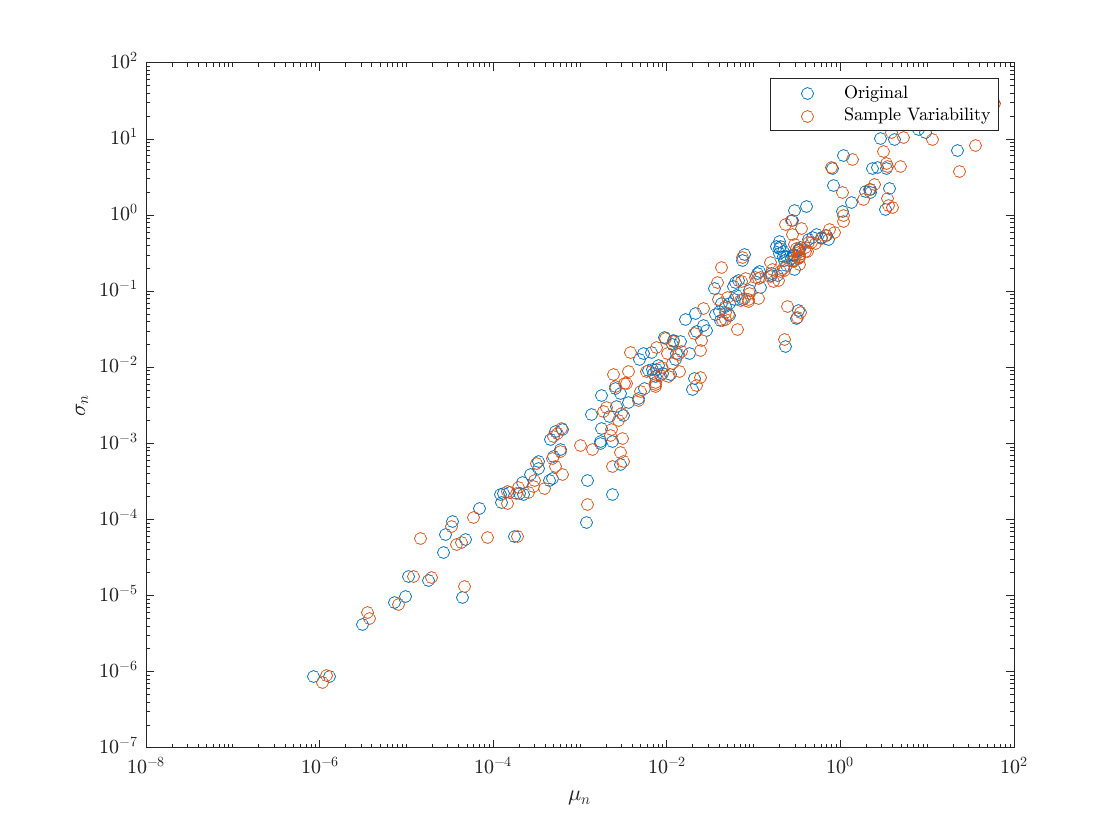


xlabel('$\mu_n$')
ylabel('$\sigma_n$')

legend('Original', 'Sample Variability')

"Between" vs "Within" sample variability

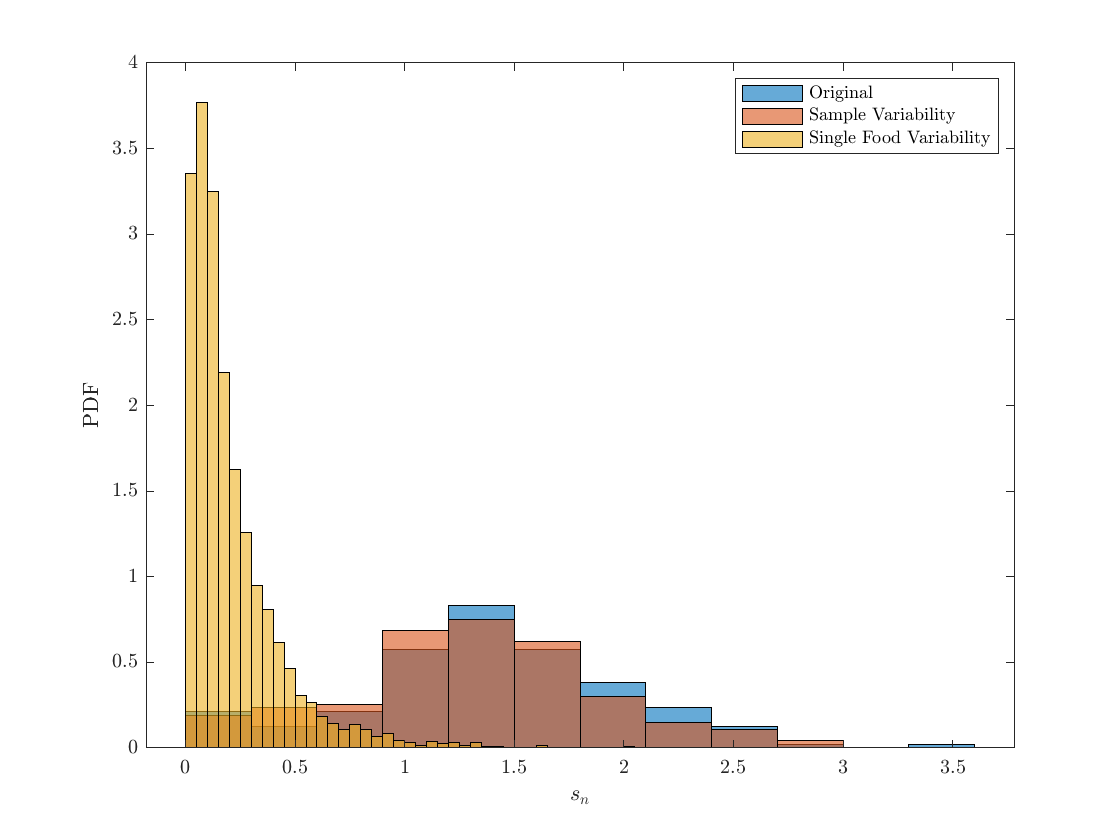

figure,
histogram(tableresults.avgfoodstdlog, 'Normalization', 'PDF')
hold on
histogram(tableresults.totalstdlog, 'Normalization', 'PDF')
hold on
histogram(tableresultsALL.totalstdlog(tableresultsALL.numdatapoints>1), 'Normalization', 'PDF')
xlabel('$s_n$')
ylabel('PDF')
legend('Original', 'Sample Variability', 'Single Food Variability')

Relation with the number of datapoints per sample

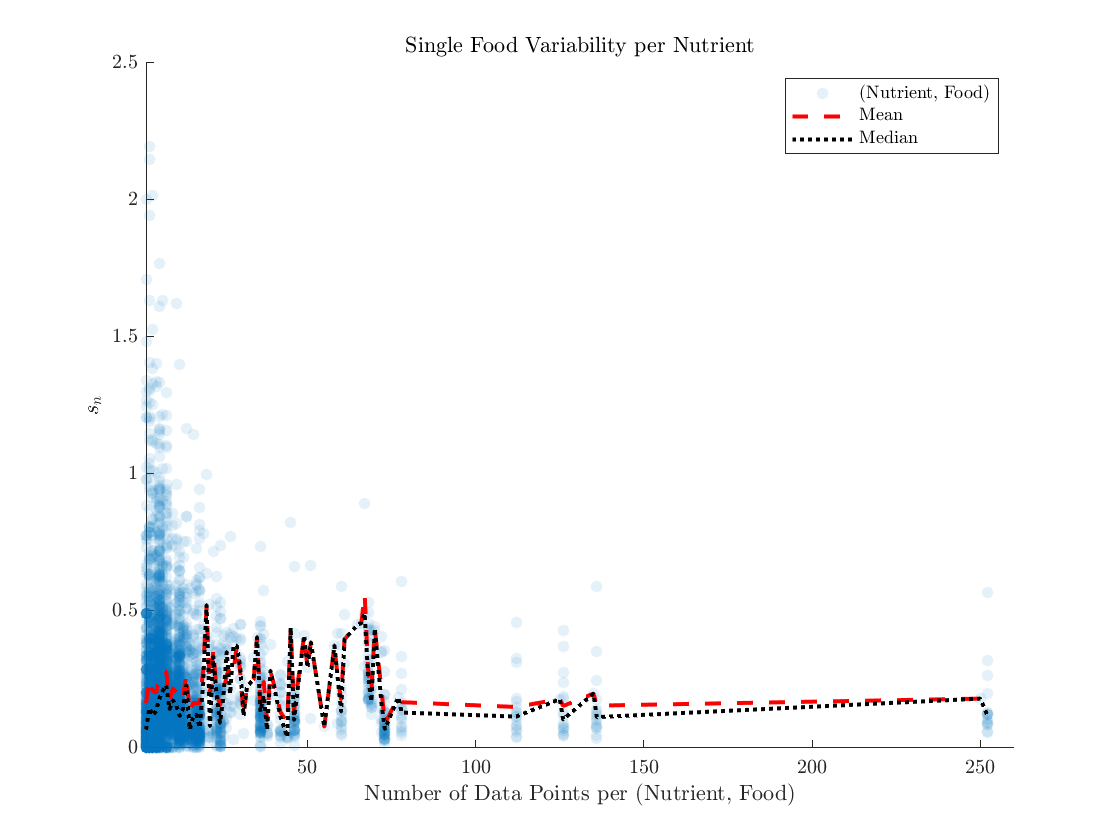

figure,
s=scatter(tableresultsALL.numdatapoints(tableresultsALL.numdatapoints>1), tableresultsALL.totalstdlog(tableresultsALL.numdatapoints>1), 'filled');
s.MarkerFaceAlpha=0.1;
hold on
unp=unique(tableresultsALL.numdatapoints(tableresultsALL.numdatapoints>1));
meansfornp=zeros(length(unp),1);
medianfornp=zeros(length(unp),1);

for ind=1:length(unp)
    meansfornp(ind)=mean(tableresultsALL.totalstdlog(tableresultsALL.numdatapoints==unp(ind)));
    medianfornp(ind)=median(tableresultsALL.totalstdlog(tableresultsALL.numdatapoints==unp(ind)));

end

p1=plot(unp,meansfornp, 'r--', 'LineWidth',2);
hold on
p2=plot(unp,medianfornp, 'k:', 'LineWidth',2);

xlim([2 260])
xlabel('Number of Data Points per (Nutrient, Food)')
ylabel('$s_n$')
legend('(Nutrient, Food)', 'Mean', 'Median')
title('Single Food Variability per Nutrient')